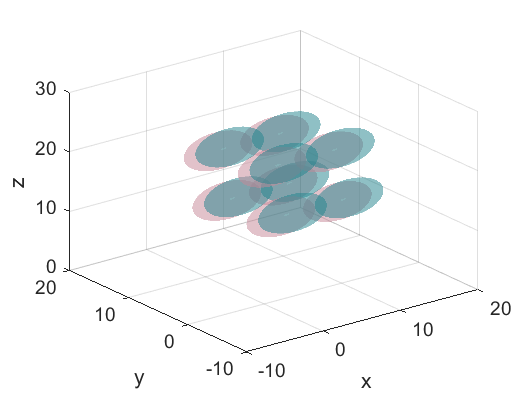

clear all
ax = axes('XLim',[-10 20],'YLim',[-10 20],'ZLim',[0 30]);
view(3)

R11=2.57;
R31=3.98;
R12=6.71;
R32=6.90;
u31=[0.630;-0.496;0.598];

[x1,y1,z1] = ellipsoid(5.827,2.870,11.960,R11,R11,R31,20);
[x2,y2,z2] = ellipsoid(7.573,7.125,8.770,R11,R11,R31,20);

hold on

h(1)=surf(x1,y1,z1,'FaceColor',[36,133,142]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);

g(1)=surf(x2,y2,z2,'FaceColor',[200,137,153]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);




grid on
hold off


t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);
t4 = hgtransform('Parent',ax);
t5 = hgtransform('Parent',ax);
t6 = hgtransform('Parent',ax);
t7 = hgtransform('Parent',ax);
t8 = hgtransform('Parent',ax);

r1 = hgtransform('Parent',ax);
r2 = hgtransform('Parent',ax);
r3 = hgtransform('Parent',ax);
r4 = hgtransform('Parent',ax);
r5 = hgtransform('Parent',ax);
r6 = hgtransform('Parent',ax);
r7 = hgtransform('Parent',ax);
r8 = hgtransform('Parent',ax);

Rx = makehgtform('xrotate',39.7*pi/180);
Ry = makehgtform('yrotate',53.3*pi/180);
Rz = makehgtform('zrotate',-38.2*pi/180);

Ta = makehgtform('translate',[7.34 0 0]);
Tb = makehgtform('translate',[-1.498 7.19 0]);
Tc = makehgtform('translate',[-2.812 -2.193 10.365]);
Tr1 = makehgtform('translate',[5.827 2.870 11.960]);
Tr2 = makehgtform('translate',[7.573 7.125 8.770]);


set(h,'Parent',t1);
set(g,'Parent',r1);


h2 = copyobj(h,t2);
h3 = copyobj(h,t3);
h4 = copyobj(h,t4);
h5 = copyobj(h,t5);
h6 = copyobj(h,t6);
h7 = copyobj(h,t7);
h8 = copyobj(h,t8);

g2 = copyobj(g,r2);
g3 = copyobj(g,r3);
g4 = copyobj(g,r4);
g5 = copyobj(g,r5);
g6 = copyobj(g,r6);
g7 = copyobj(g,r7);
g8 = copyobj(g,r8);


set(t1,'Matrix',Tr1*Rz*Ry*Rz/Tr1)
set(t2,'Matrix',Ta*Tr1*Rz*Ry*Rz/Tr1)
set(t3,'Matrix',Tc*Tr1*Rz*Ry*Rz/Tr1)
set(t4,'Matrix',Tb*Tr1*Rz*Ry*Rz/Tr1)
set(t5,'Matrix',Ta*Tb*Tr1*Rz*Ry*Rz/Tr1)
set(t6,'Matrix',Ta*Tc*Tr1*Rz*Ry*Rz/Tr1)
set(t7,'Matrix',Tb*Tc*Tr1*Rz*Ry*Rz/Tr1)
set(t8,'Matrix',Ta*Tb*Tc*Tr1*Rz*Ry*Rz/Tr1)



set(r1,'Matrix',Tr2*Rz*Ry*Rz/Tr2)
set(r2,'Matrix',Ta*Tr2*Rz*Ry*Rz/Tr2)
set(r3,'Matrix',Tc*Tr2*Rz*Ry*Rz/Tr2)
set(r4,'Matrix',Tb*Tr2*Rz*Ry*Rz/Tr2)
set(r5,'Matrix',Ta*Tb*Tr2*Rz*Ry*Rz/Tr2)
set(r6,'Matrix',Ta*Tc*Tr2*Rz*Ry*Rz/Tr2)
set(r7,'Matrix',Tb*Tc*Tr2*Rz*Ry*Rz/Tr2)
set(r8,'Matrix',Ta*Tb*Tc*Tr2*Rz*Ry*Rz/Tr2)


xlabel('x');
ylabel('y');
zlabel('z');
drawnow

for i = 1:360
   camorbit(1,0,'data',[0 0 1])

   drawnow
end